Lx = 8;
Ly = 6;
Nx = 50;
Ny = 50;
m = createMesh2D(Nx,Ny,Lx,Ly);


%边界
D_val = 0.01; %diffusion coeeficient
BC = createBC(m); % all Neumann boundary condition structure
a = BC.left.a;
BC.left.a = -D_val*a;
BC.right.a = -D_val*a;
BC.top.a = -D_val*a;
BC.bottom.a = -D_val*a;

[xb,yb] = Force_ring_xy(0,m.cellcenters.y);
BC.left.b = transpose(xb);
[xb,yb] = Force_ring_xy(Lx,m.cellcenters.y);
BC.right.b = transpose(xb);

[xb,yb] = Force_ring_xy(m.cellcenters.x,0);
BC.bottom.b = transpose(yb);
[xb,yb] = Force_ring_xy(m.cellcenters.x,Ly);
BC.top.b = transpose(yb);

c = 0.01*ones(1,Nx);
BC.left.c = -c;
BC.right.c = c;
BC.top.c = c;
BC.bottom.c = -c;

%diffussion term
D = createCellVariable(m, D_val); % assign dif. coef. to all the cells
Dave = harmonicMean(D); % convert a cell variable to face variable

%convection term
u_face = createFaceVariable(m, 1); % assign velocity value to cell faces
[x,y] = ndgrid(m.facecenters.x, m.cellcenters.y);
[xv,yv] = Force_ring_xy(x,y);
u_face.xvalue = xv;

[x,y] = ndgrid(m.cellcenters.x, m.facecenters.y)

x =     0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800    0.0800
    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0.2400    0

y =          0    0.1200    0.2400    0.3600    0.4800    0.6000    0.7200    0.8400    0.9600    1.0800    1.2000    1.3200    1.4400    1.5600    1.6800    1.8000    1.9200    2.0400    2.1600    2.2800    2.4000    2.5200    2.6400    2.7600    2.8800    3.0000    3.1200    3.2400    3.3600    3.4800    3.6000    3.7200    3.8400    3.9600    4.0800    4.2000    4.3200    4.4400    4.5600    4.6800    4.8000    4.9200    5.0400    5.1600    5.2800    5.4000    5.5200    5.6400    5.7600    5.8800
         0    0.1200    0.2400    0.3600    0.4800    0.6000    0.7200    0.8400    0.9600    1.0800    1.2000    1.3200    1.4400    1.5600    1.6800    1.8000    1.9200    2.0400    2.1600    2.2800    2.4000    2.5200    2.6400    2.7600    2.8800    3.0000    3.1200    3.2400    3.3600    3.4800    3.6000    3.7200    3.8400    3.9600    4.0800    4.2000    4.3200    4.4400    4.5600    4.6800    4.8000    4.9200    5.0400    5.1600    5.2800    5.4000    5.5200    5.6400    5.7600    5

s =   Surface - 属性:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [52×1 double]
           YData: [52×1 double]
           ZData: [52×52 double]
           CData: [52×52 double]

  显示 所有属性


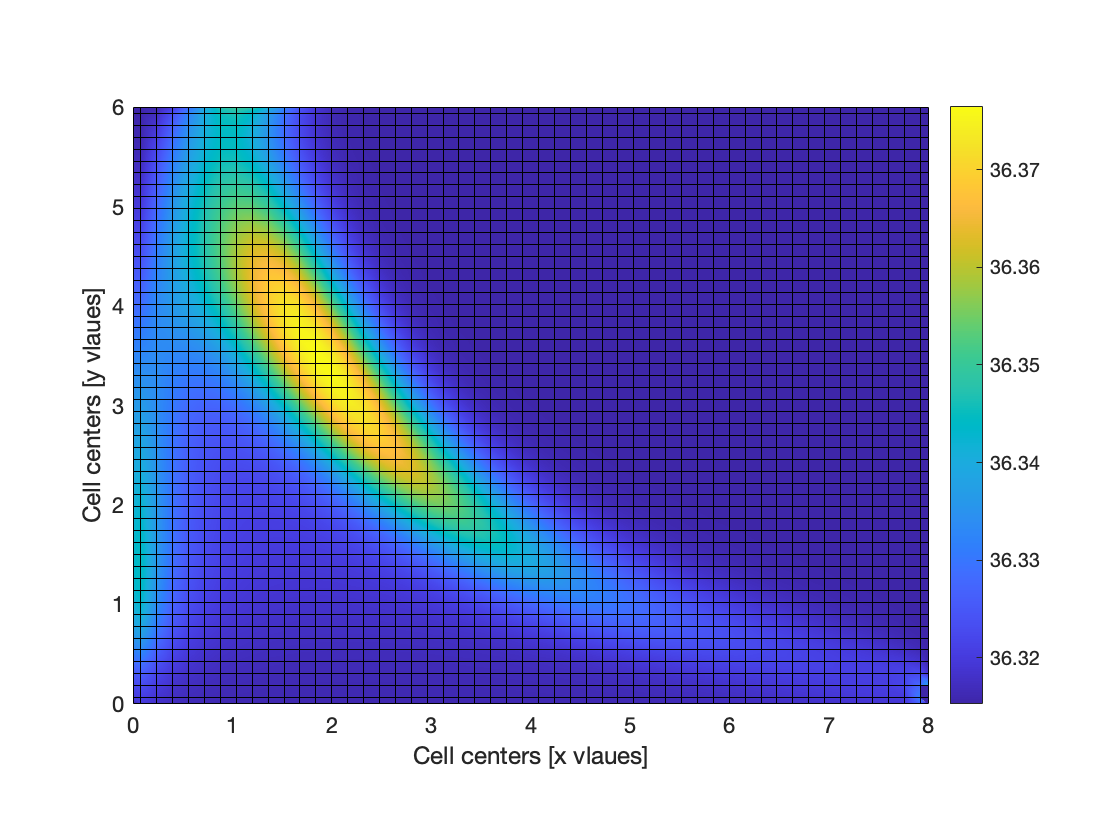

[xv,yv] = Force_ring_xy(x,y);
u_face.yvalue = yv;

%solve
Mconv =  convectionTerm(u_face); % convection term, central, second order
Mdiff = diffusionTerm(Dave); % diffusion term
[Mbc, RHS] = boundaryCondition(BC); % boundary condition discretization
M = Mconv-Mdiff+Mbc; % matrix of coefficient for central scheme
c = solvePDE(m, M, RHS); % solve for the central scheme
c.value = c.value-min(min(c.value));
c.value = log(c.value);
%c.value = 
visualizeCells2D(c);